% Signal Processing for Long-term Tianjin Data

% load data
close all
clear
clc

load_data = load('long_term_tianjin_train_val.mat');
data_mobile = load_data.data_mobile;
data_static = load_data.data_static;

% For one static sensor
long_term_s = sortrows(data_static{1}, 'time');

time_s    = long_term_s.time;
pm2d5_s   = long_term_s.pm2d5;

% Clean data (missing values)
sum(isnan(pm2d5_s)) % any missing?

ans = 0

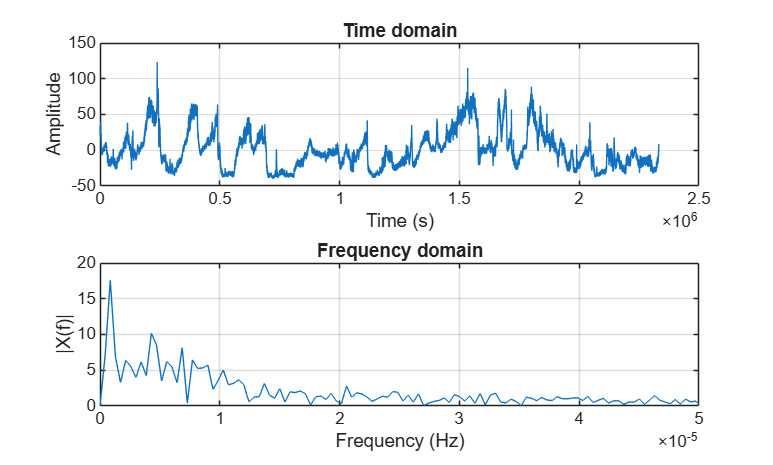

[time_s, ia] = unique(time_s); % drop duplicate timestamps
pm2d5_s = pm2d5_s(ia);

% Plot FFT
step = median(diff(time_s)); % typical sampling interval
Fs = 1/seconds(step);  % Hz (samples per second)

N = length(pm2d5_s);
t = (0:N-1)'/Fs; % time axis in seconds

% Remove the mean so the DC spike doesn't dominate the spectrum
x = detrend(pm2d5_s, 0);

% FFT
X = fft(x);

figure
subplot(2,1,1)
plot(t, real(x))
xlabel('Time (s)'), ylabel('Amplitude')
title('Time domain'), grid on

subplot(2,1,2)
% One-sided spectrum for real signals
P2 = abs(X/N);
P1 = P2(1:floor(N/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:floor(N/2))/N;
plot(f, P1)
xlim([0, 0.00005])

xlabel('Frequency (Hz)'), ylabel('|X(f)|')
title('Frequency domain'), grid on

- Most of the energy in the signal is the lower frequencies (peak at 8.57E-07 Hz = 13.5 days)

- No strong daily cycle (1 day = 1.16E-5 Hz, no significant peak at this point)

- Slow components = signal --> try low-pass filter

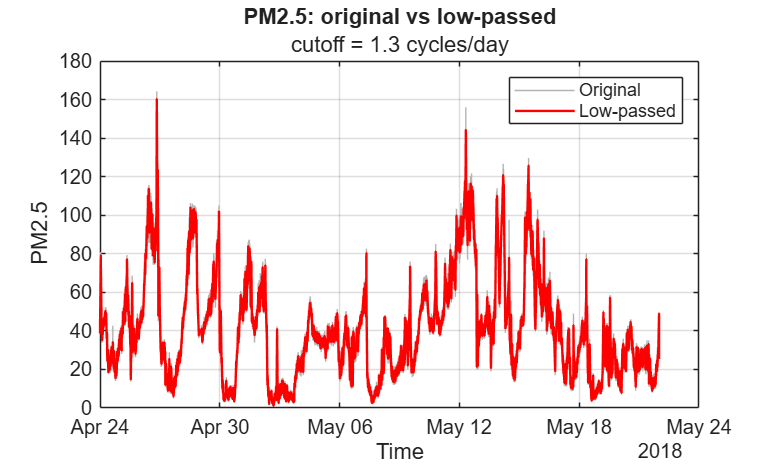

% --- Low-pass filter ---
cut = 1.5e-5; % cut-off point from FFT where most of the signal shows up
stpns = 0.85; % default for lowpass filter
lowpassed_data = lowpass(pm2d5_s, cut, Fs, 'Steepness', stpns);

%% Plot low-passed data against time

figure
plot(time_s, pm2d5_s, 'Color', [0.7 0.7 0.7]), hold on
plot(time_s, lowpassed_data, 'r-', 'LineWidth', 1.2)
xlabel('Time'), ylabel('PM2.5')
legend('Original', 'Low-passed')
title('PM2.5: original vs low-passed' , sprintf('cutoff = %.1f cycles/day', cut*86400))
grid on

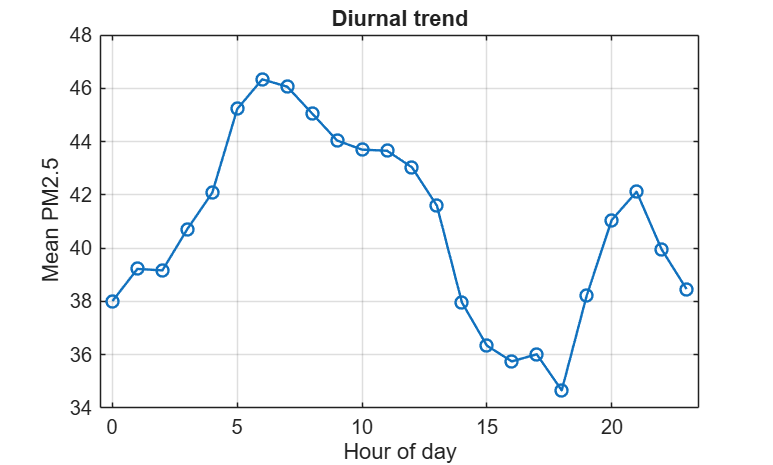

%% Diurnal trend
hr = hour(time_s);                              % hour of day (0-23) for each sample
mu = accumarray(hr+1, pm2d5_s, [24 1], @mean);  % average PM2.5 for each hour of day

figure
plot(0:23, mu, 'o-', 'LineWidth', 1.2)
xlim([-0.5 23.5]), grid on
xlabel('Hour of day'), ylabel('Mean PM2.5')
title('Diurnal trend')

% Test moving average window
win_size = [1,20*60,20*60*12];
name = {'Raw Data','60-min Moving Average','12-hour Moving average'};

hold on;

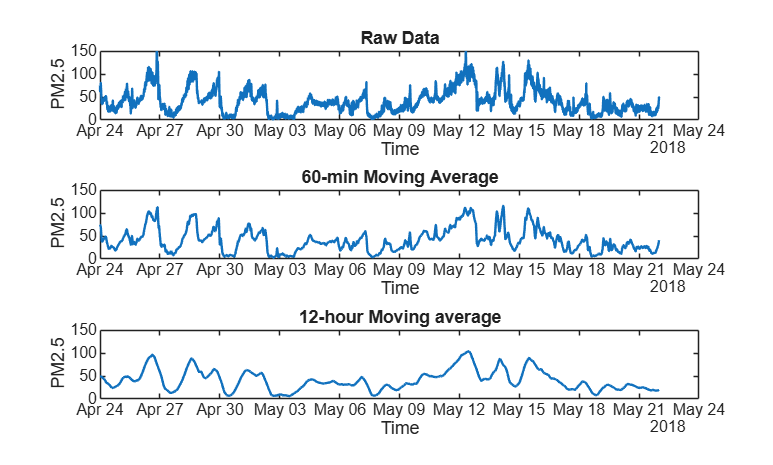

for i = 1:length(win_size)
    mv_data = movmean(pm2d5_s, win_size(i));
    subplot(3, 1, i);
    plot(time_s, mv_data, 'LineWidth', 1.2)
    title(name{i})
    xlabel('Time')
    ylabel('PM2.5')
    ylim([0 150])
end
hold off;

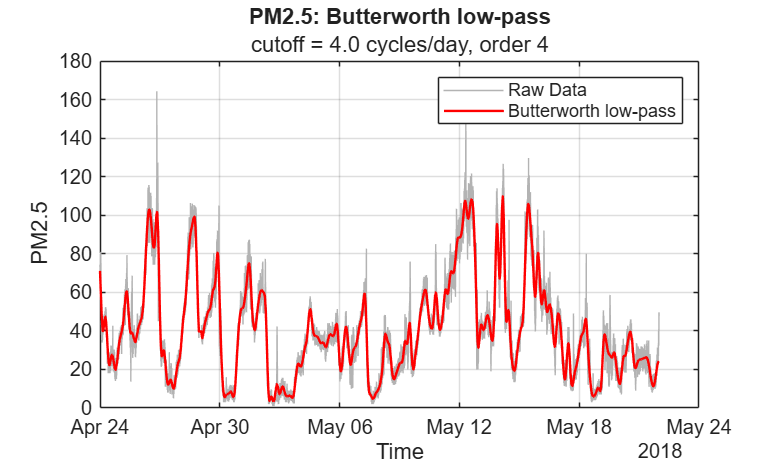

% Test butterworth low-pass model
%% Butterworth low-pass filter (on 5-min averaged data)
% Average 3-s data to 5-min first so a cutoff of a few cycles/day is numerically stable

fc_cpd = 4;                       % cutoff in cycles/day (periods longer than ~6 h are kept)
d_bw = designfilt('lowpassiir', 'FilterOrder', 4, 'HalfPowerFrequency', fc_cpd/86400, ...
    'SampleRate', Fs, 'DesignMethod', 'butter');
pm5_bw = filtfilt(d_bw, pm2d5_s);     % zero-phase (uses future samples; use filter(d_bw, pm5) if causal)

figure
plot(time_s, pm2d5_s, 'Color', [0.7 0.7 0.7]), hold on
plot(time_s, pm5_bw, 'r-', 'LineWidth', 1.2)
xlabel('Time'), ylabel('PM2.5'), grid on
legend('Raw Data', 'Butterworth low-pass')
title('PM2.5: Butterworth low-pass', sprintf('cutoff = %.1f cycles/day, order 4', fc_cpd))

- **The signal is mostly slow.** The red line follows the gray one closely almost everywhere. Most of the structure is multi-day episodes: highs around Apr 26-28 (about 100) and May 12-15 (about 110), and clean periods near 0-10 around Apr 30-May 2 and May 6-8. A 4 cycles/day cutoff keeps all of this.

- **Filter removes brief spikes**

- **Peaks are not as accurately defined with the filter **- smoothing lowers the extreme values, but maintains underlying trend

- **Quick-drop edges are mostly preserved **- 4 cycles/day isn’t oversmoothing.

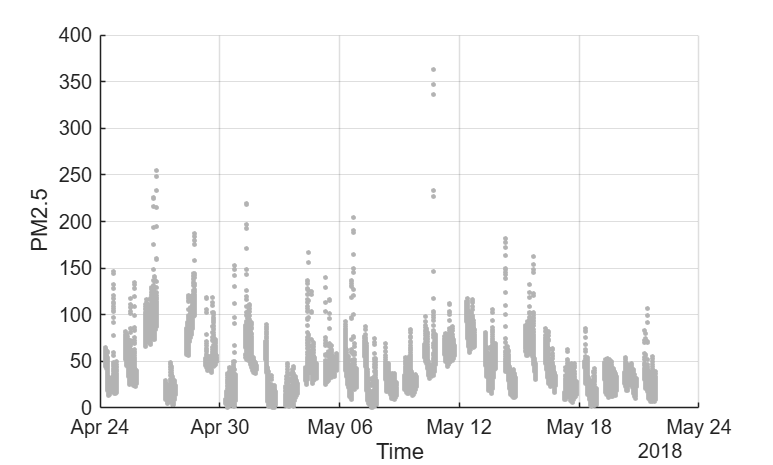

% For one mobile sensor
long_term_m = sortrows(data_mobile{1}, 'time');

time_m    = long_term_m.time;
pm2d5_m   = long_term_m.pm2d5;

% plot uncleaned data
figure
scatter(time_m, pm2d5_m, 6, [0.7 0.7 0.7], 'filled')
xlabel('Time'), ylabel('PM2.5'), grid on

% Clean data (missing values)
sum(isnan(pm2d5_m)) % any missing?

ans = 0

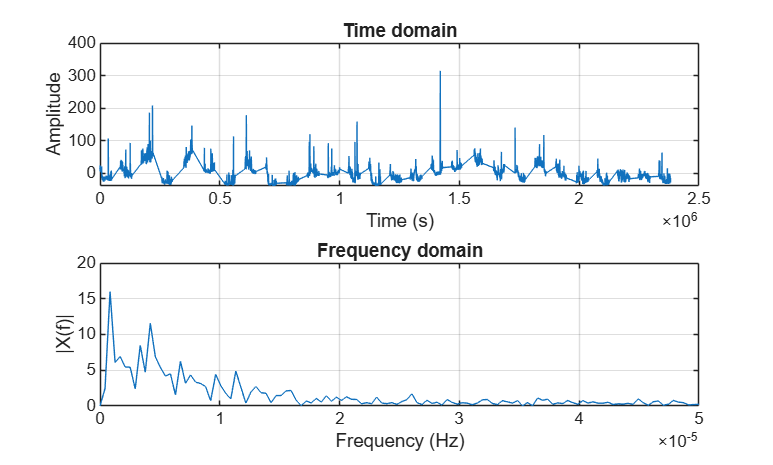

ok = ~isnan(pm2d5_m) & ~isnat(time_m);     % keep only valid rows
time_m  = time_m(ok);
pm2d5_m = pm2d5_m(ok);

[time_m, ia] = unique(time_m);              % drop duplicate timestamps
pm2d5_m = pm2d5_m(ia);

tt = retime(timetable(time_m, pm2d5_m), 'regular', 'linear', 'TimeStep', seconds(3));
pm_clean = fillmissing(tt.pm2d5_m, 'linear');   % fill any leftover NaNs
time_clean = tt.time_m;

% Plot FFT
step = median(diff(time_clean)); % typical sampling interval
Fs = 1/seconds(step);  % Hz (samples per second)

N = length(pm_clean);
t = (0:N-1)'/Fs; % time axis in seconds

% Remove the mean so the DC spike doesn't dominate the spectrum
x = detrend(pm_clean, 0);

% FFT
X = fft(x);

figure
subplot(2,1,1)
plot(t, real(x))
xlabel('Time (s)'), ylabel('Amplitude')
title('Time domain'), grid on

subplot(2,1,2)
% One-sided spectrum for real signals
P2 = abs(X/N);
P1 = P2(1:floor(N/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:floor(N/2))/N;
plot(f, P1)
xlim([0, 0.00005])

xlabel('Frequency (Hz)'), ylabel('|X(f)|')
title('Frequency domain'), grid on

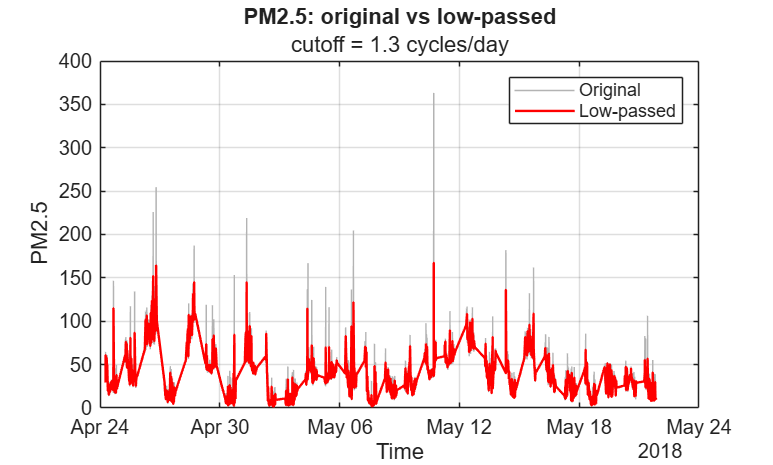

% --- Low-pass filter ---
cut = 1.5e-5; % cut-off point from FFT where most of the signal shows up
stpns = 0.85; % default for lowpass filter
lowpassed_data_m = lowpass(pm_clean, cut, Fs, 'Steepness', stpns);

%% Plot low-passed data against time

figure
plot(time_m, pm2d5_m, 'Color', [0.7 0.7 0.7]), hold on
plot(time_clean, lowpassed_data_m, 'r-', 'LineWidth', 1.2)
xlabel('Time'), ylabel('PM2.5')
legend('Original', 'Low-passed')
title('PM2.5: original vs low-passed' , sprintf('cutoff = %.1f cycles/day', cut*86400))
grid on
% Test moving average window
win_size = [1,20*60,20*60*12];
name = {'Raw Data','60-min Moving Average','12-hour Moving average'};

hold on;

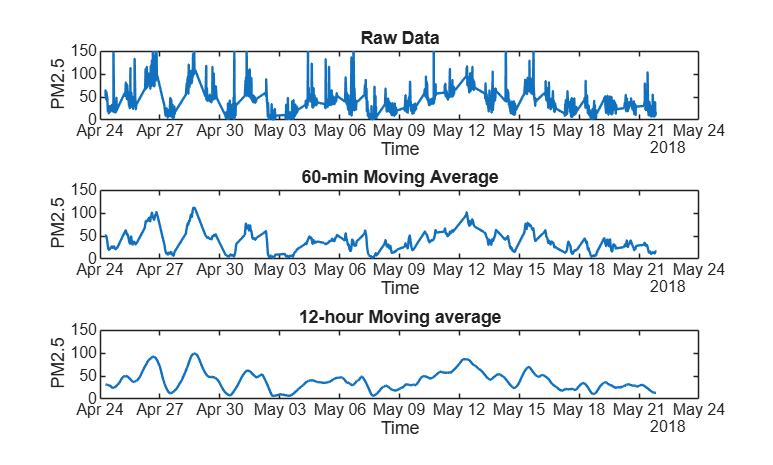

for i = 1:length(win_size)
    mv_data = movmean(pm_clean, win_size(i));
    subplot(3, 1, i);
    plot(time_clean, mv_data, 'LineWidth', 1.2)
    title(name{i})
    xlabel('Time')
    ylabel('PM2.5')
    ylim([0 150])
end
hold off;

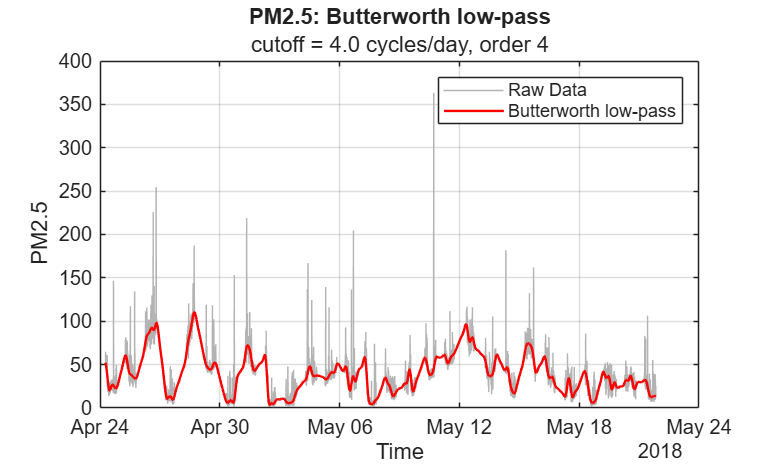

% Test butterworth low-pass model
%% Butterworth low-pass filter (on 5-min averaged data)
% Average 3-s data to 5-min first so a cutoff of a few cycles/day is numerically stable

fc_cpd = 4;                       % cutoff in cycles/day (periods longer than ~6 h are kept)
d_bw = designfilt('lowpassiir', 'FilterOrder', 4, 'HalfPowerFrequency', fc_cpd/86400, ...
    'SampleRate', Fs, 'DesignMethod', 'butter');
pm5_bw = filtfilt(d_bw, pm_clean);     % zero-phase (uses future samples; use filter(d_bw, pm5) if causal)

figure
plot(time_m, pm2d5_m, 'Color', [0.7 0.7 0.7]), hold on
plot(time_clean, pm5_bw, 'r-', 'LineWidth', 1.2)
xlabel('Time'), ylabel('PM2.5'), grid on
legend('Raw Data', 'Butterworth low-pass')
title('PM2.5: Butterworth low-pass', sprintf('cutoff = %.1f cycles/day, order 4', fc_cpd))